A1 = 28;  % Área do tanque 1 (cm^2)
A2 = 32;  % Área do tanque 2 (cm^2)
A3 = 28;  % Área do tanque 3 (cm^2)
A4 = 32;  % Área do tanque 4 (cm^2)
a1 = 0.071; % Constante de vazão do tanque 1 (cm^2)
a2 = 0.057; % Constante de vazão do tanque 2 (cm^2)
a3 = 0.071; % Constante de vazão do tanque 3 (cm^2)
a4 = 0.057; % Constante de vazão do tanque 4 (cm^2)
h1_0 = 12.4; % Nível de equilíbrio do tanque 1 (cm)
h2_0 = 12.7; % Nível de equilíbrio do tanque 2 (cm)
h3_0 = 1.8; % Nível de equilíbrio do tanque 3 (cm)
h4_0 = 1.4; % Nível de equilíbrio do tanque 4 (cm)
g = 981;  % Aceleração da gravidade (cm/s^2)
k1 = 3.33;   % Vazão da bomba 1 (cm^3/s)
k2 = 3.35;   % Vazão da bomba 2 (cm^3/s)
gamma1 = 0.7; % Coeficiente de distribuição da bomba 1
gamma2 = 0.6; % Coeficiente de distribuição da bomba 2
kc = 0.5; % Constante do controlador

% Constantes de tempo dos tanques
T1 = (A1 / a1) * sqrt(2 * h1_0 / g);
T2 = (A2 / a2) * sqrt(2 * h2_0 / g);
T3 = (A3 / a3) * sqrt(2 * h3_0 / g);
T4 = (A4 / a4) * sqrt(2 * h4_0 / g);

% Matriz A do sistema
A = [...
    -1/T1,     0,      A3/(A1*T3),    0;
    0,       -1/T2,    0,            A4/(A2*T4);
    0,        0,     -1/T3,          0;
    0,        0,      0,           -1/T4];

% Matriz B do sistema
B = [...
    gamma1*k1/A1,        0;
    0,                   gamma2*k2/A2;
    0,    (1-gamma2)*k2/A3;
    (1-gamma1)*k1/A4,                   0];

% Matriz C do sistema (medindo níveis dos tanques 1 e 2)
C = [kc, 0, 0, 0;
     0, kc, 0, 0];

% Matriz D do sistema (nenhuma ação direta das entradas sobre as saídas)
D = zeros(2, 2);

% Criar o sistema em espaços de estados
sys = ss(A, B, C, D);

% Mostrar o sistema
disp('Sistema em Espaços de Estado:');

Sistema em Espaços de Estado:


disp(sys);

  2×2 ss array with properties:

                A: [4×4 double]
                B: [4×2 double]
                C: [2×4 double]
                D: [2×2 double]
                E: []
           Scaled: 0
        StateName: {4×1 cell}
        StatePath: {4×1 cell}
        StateUnit: {4×1 cell}
    InternalDelay: [0×1 double]
       InputDelay: [2×1 double]
      OutputDelay: [2×1 double]
        InputName: {2×1 cell}
        InputUnit: {2×1 cell}
       InputGroup: [1×1 struct]
       OutputName: {2×1 cell}
       OutputUnit: {2×1 cell}
      OutputGroup: [1×1 struct]
            Notes: [0×1 string]
         UserData: []
             Name: ''
               Ts: 0
         TimeUnit: 'seconds'
     SamplingGrid: [1×1 struct]



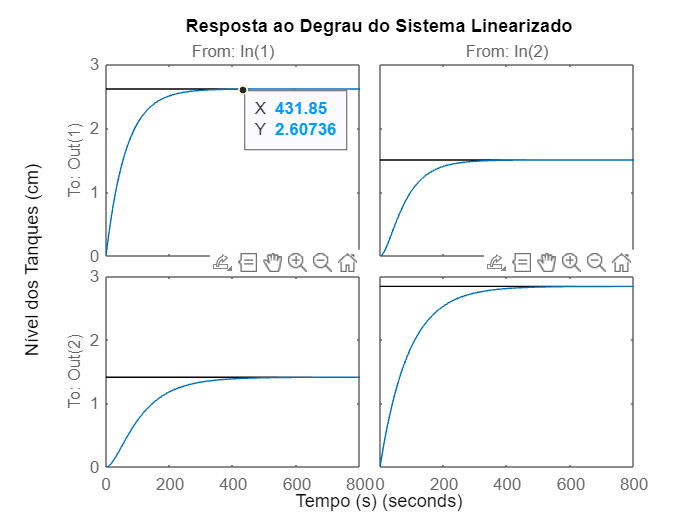


% Análise de resposta ao degrau
figure;
step(sys);
title('Resposta ao Degrau do Sistema Linearizado');
xlabel('Tempo (s)');
ylabel('Nível dos Tanques (cm)');

% Obter a Função de Transferência (FT) do sistema em espaços de estado
G = tf(sys);

% Obter polos do sistema
p = pole(G);
disp('Polos do sistema:');

Polos do sistema:


disp(p);

   -0.0159
   -0.0333
   -0.0111
   -0.0419
   -0.0159
   -0.0111




% Obter zeros do sistema
z = zero(G);

disp('Zeros do sistema:');

Zeros do sistema:


disp(z);

   -0.0580
   -0.0111
   -0.0172
   -0.0159




% Mostrar a função de transferência
disp('Função de Transferência do Sistema:');

Função de Transferência do Sistema:


G

G =
 
  From input 1 to output...
         0.04163
   1:  -----------
       s + 0.01595
 
                0.0005204
   2:  ---------------------------
       s^2 + 0.04441 s + 0.0003691
 
  From input 2 to output...
                0.001002
   1:  ---------------------------
       s^2 + 0.05781 s + 0.0006676
 
         0.03141
   2:  -----------
       s + 0.01107
 
Continuous-time transfer function.


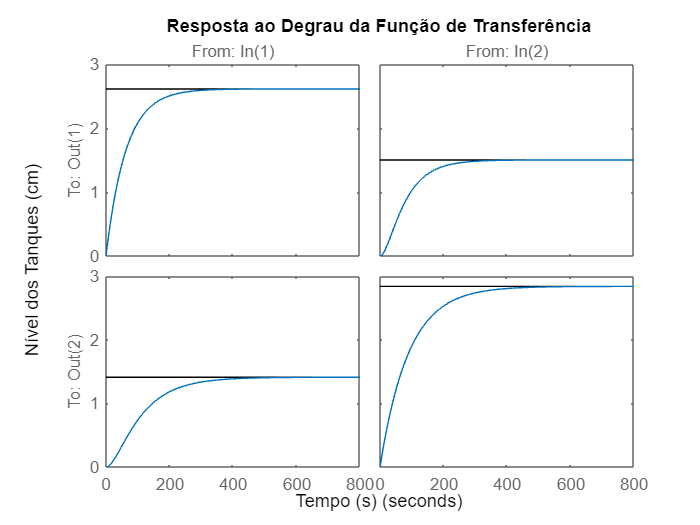


% Plotar a resposta ao degrau da FT para comparação
figure;
step(G);
title('Resposta ao Degrau da Função de Transferência');
xlabel('Tempo (s)');
ylabel('Nível dos Tanques (cm)');

Controlador PI de acordo com a proposta do artigo, iremos usar os mesmos valores.

s = tf('s');
C1 = 1.5*(1+1/110*s);
C2 = 0.12*(1+1/220*s);